# Levinson

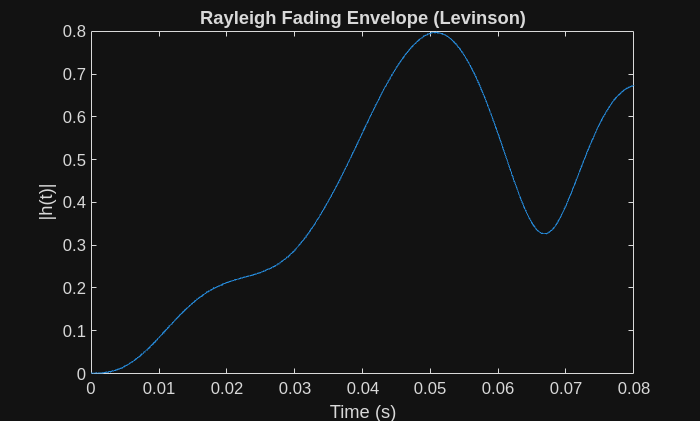

v = 3;    % 30m/s
fc = 2e9;  % 2GHz
B = 1e5;   % 100kHz
Ts = 1e-5; % 10microseconds
N = 8000;

p = 500;
C = 3e8;
fd = v*fc/C;

t = (0:N-1)*Ts;
h = utils.levinsonFilter(fd, Ts, p, N);
% --- Envelope plot ---
figure;
plot(t, abs(h));
xlabel('Time (s)');
ylabel('|h(t)|');
title('Rayleigh Fading Envelope (Levinson)');

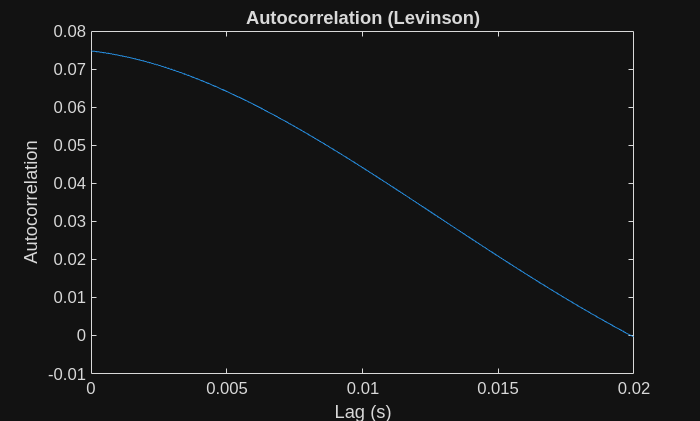

Rh_avg = [];
iter = 200;
for i= 1:iter
    % --- Autocorrelation estimate ---
    h = utils.levinsonFilter(fd, Ts, p, N);
    [Rh_est_full, lags_full] = xcorr(h, 'biased');
    
    % Keep only non-negative lags
    idx = lags_full >= 0;
    lags = lags_full(idx);
    Rh_est = Rh_est_full(idx);
    if isempty(Rh_avg)
        Rh_avg = Rh_est;
    else
        Rh_avg = Rh_est + Rh_avg;
    end
end

Rh_avg = Rh_avg/iter;
% Rh_avg = Rh_avg/Rh_avg(1);

m = 0:p;
maxLag = 2000;
R = besselj(0, 2*pi*fd*lags(1:maxLag)*Ts);
% --- Plot comparison ---
xlags = lags(1:maxLag)*Ts;
figure;
plot(xlags, real(Rh_avg(1:maxLag)));
% hold on;
% plot(xlags, R, 'r--', 'LineWidth', 1.5);

% legend('Estimated','Theoretical');
xlabel('Lag (s)');
ylabel('Autocorrelation');
title('Autocorrelation (Levinson)');

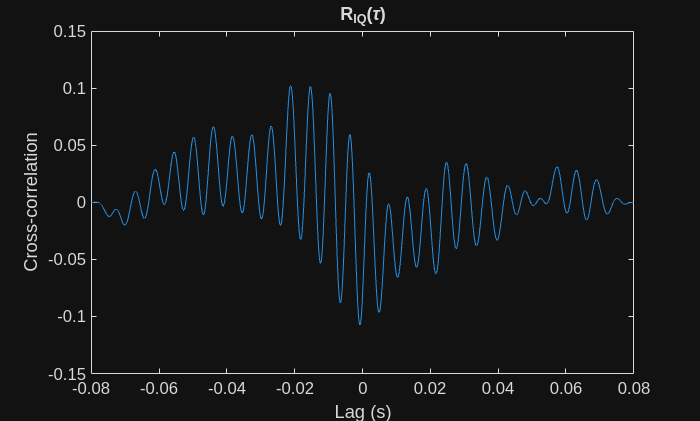

v = 30;    % 30m/s
fc = 2e9;  % 2GHz
B = 1e5;   % 100kHz
Ts = 1e-5; % 10microseconds
N = 8000;

p = 50;
C = 3e8;
fd = v*fc/C;

iter = 100;
Riq_avg = 0;
for i = 1:iter
    h = utils.levinsonFilter(fd, Ts, p, N);
    
    hI = real(h);
    hQ = imag(h);
    % w = (randn(1, N) + 1j*randn(1, N))/sqrt(2); hI = real(w); hQ = imag(w);
    
    [Riq, lags] = xcorr(hI, hQ, 'biased');
    % compute Riq
    Riq_avg = Riq_avg + Riq;
end
Riq_avg = Riq_avg / iter;
% idx = abs(lags) < 50;
% plot(lags(idx)*Ts, Riq(idx));
figure;
plot(lags*Ts, Riq);
xlabel('Lag (s)');
ylabel('Cross-correlation');
title('R_{IQ}(\tau)');

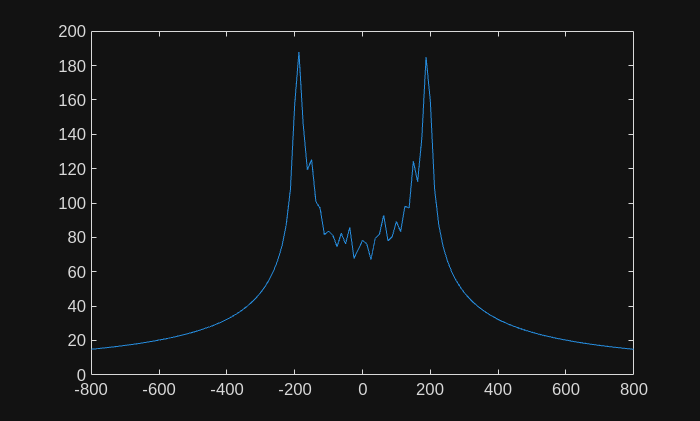

close all;
% plot(abs(fftshift(fft(R(1:maxLag)))))
% hold on;
F = fft(Rh_avg);
Nfft = length(F);
f = (-Nfft/2: 1: Nfft/2-1)/(Nfft*Ts);
plot(f, abs(fftshift(F)))
xlim([-4*fd 4*fd])

% xlim([-10*fd 2*fd])
fd

fd = 200

# Smith's Model

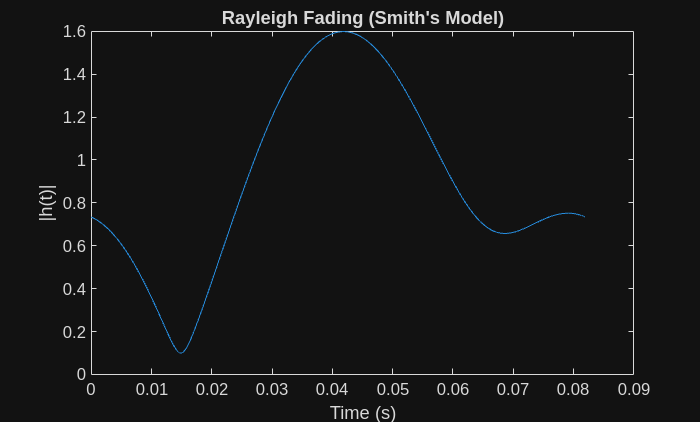

v = 3;    % 30m/s
fc = 2e9;  % 2GHz
B = 1e5;   % 100kHz
Ts = 1e-5; % 10microseconds
N = 8192;

p = 500;
C = 3e8;
fd = v*fc/C;

[h, t] = utils.smithsFilter(fd, Ts, N);

% --- Plot envelope ---
figure;
plot(t, abs(h));
xlabel('Time (s)');
ylabel('|h(t)|');
title("Rayleigh Fading (Smith's Model)");

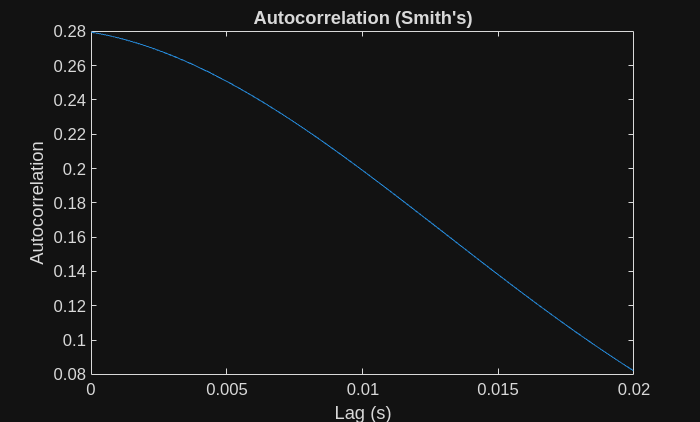

Rh_avg = [];
iter = 200;
for i= 1:iter
    % --- Autocorrelation estimate ---
    h = utils.levinsonFilter(fd, Ts, p, N);
    [Rh_est_full, lags_full] = xcorr(h, 'biased');
    
    % Keep only non-negative lags
    idx = lags_full >= 0;
    lags = lags_full(idx);
    Rh_est = Rh_est_full(idx);
    if isempty(Rh_avg)
        Rh_avg = Rh_est;
    else
        Rh_avg = Rh_est + Rh_avg;
    end
end

Rh_avg = Rh_avg/iter;
% Rh_avg = Rh_avg/Rh_avg(1);

m = 0:p;
maxLag = 2000;
R = besselj(0, 2*pi*fd*lags(1:maxLag)*Ts);
% --- Plot comparison ---
xlags = lags(1:maxLag)*Ts;
figure;
plot(xlags, real(Rh_avg(1:maxLag)));
% hold on;
% plot(xlags, R, 'r--', 'LineWidth', 1.5);

% legend('Estimated','Theoretical');
xlabel('Lag (s)');
ylabel('Autocorrelation');
title("Autocorrelation (Smith's)");

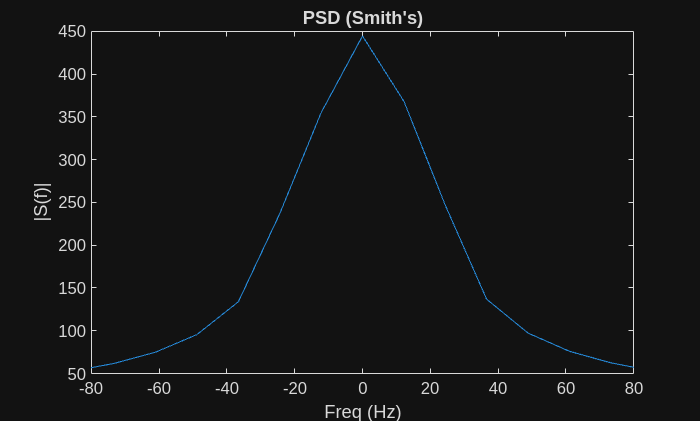


F = fft(Rh_avg);
Nfft = length(F);
f = (-Nfft/2: 1: Nfft/2-1)/(Nfft*Ts);
figure;
plot(f, abs(fftshift(F)))
xlim([-4*fd 4*fd])
xlabel('Freq (Hz)');
ylabel('|S(f)|');
title("PSD (Smith's)");


v = 30;    % 30m/s
fc = 2e9;  % 2GHz
B = 1e5;   % 100kHz
Ts = 1e-5; % 10microseconds
N = 8192;

p = 50;
C = 3e8;
fd = v*fc/C;

iter = 100;
Riq_avg = 0;
for i = 1:iter
    h = utils.smithsFilter(fd, Ts,N);
    
    hI = real(h);
    hQ = imag(h);
    % w = (randn(1, N) + 1j*randn(1, N))/sqrt(2); hI = real(w); hQ = imag(w);
    
    [Riq, lags] = xcorr(hI, hQ, 'biased');
    % compute Riq
    Riq_avg = Riq_avg + Riq;
end
Riq_avg = Riq_avg / iter;
% idx = abs(lags) < 50;
% plot(lags(idx)*Ts, Riq(idx));
figure;
plot(lags*Ts, Riq);
xlabel('Lag (s)');
ylabel('Cross-correlation');
title("R_{IQ}(\tau) (Smith's)");

# Modified Sum of Sinusoids

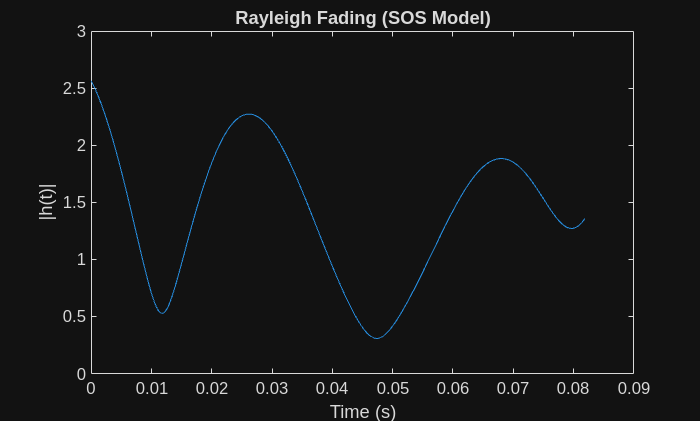

v = 3;    % 30m/s
fc = 2e9;  % 2GHz
B = 1e5;   % 100kHz
Ts = 1e-5; % 10microseconds

N0 = 32;   % Number of sinusoids

p = 50;
C = 3e8;
fd = v*fc/C;

h = utils.SOS(fd, Ts, N0, N);

figure;
plot(t, abs(h));
xlabel('Time (s)');
ylabel('|h(t)|');
title("Rayleigh Fading (SOS Model)");

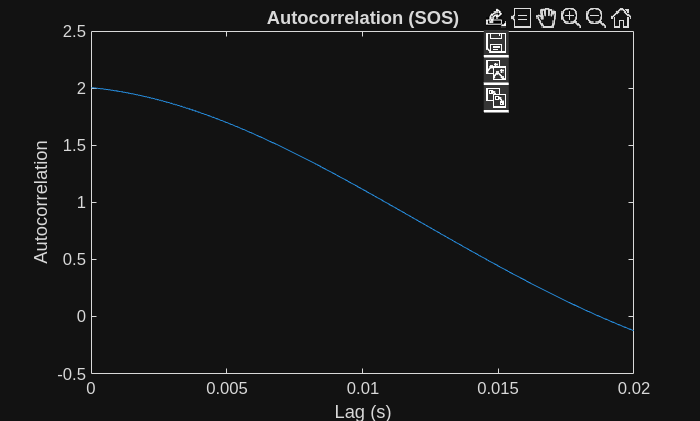

Rh_avg = [];
iter = 200;
for i= 1:iter
    % --- Autocorrelation estimate ---
    h = utils.SOS(fd, Ts, N0, N);
    [Rh_est_full, lags_full] = xcorr(h, 'biased');
    
    % Keep only non-negative lags
    idx = lags_full >= 0;
    lags = lags_full(idx);
    Rh_est = Rh_est_full(idx);
    if isempty(Rh_avg)
        Rh_avg = Rh_est;
    else
        Rh_avg = Rh_est + Rh_avg;
    end
end

Rh_avg = Rh_avg/iter;
% Rh_avg = Rh_avg/Rh_avg(1);

m = 0:p;
maxLag = 2000;
R = besselj(0, 2*pi*fd*lags(1:maxLag)*Ts);
% --- Plot comparison ---
xlags = lags(1:maxLag)*Ts;
figure;
plot(xlags, real(Rh_avg(1:maxLag)));
% hold on;
% plot(xlags, R, 'r--', 'LineWidth', 1.5);

% legend('Estimated','Theoretical');
xlabel('Lag (s)');
ylabel('Autocorrelation');
title("Autocorrelation (SOS)");

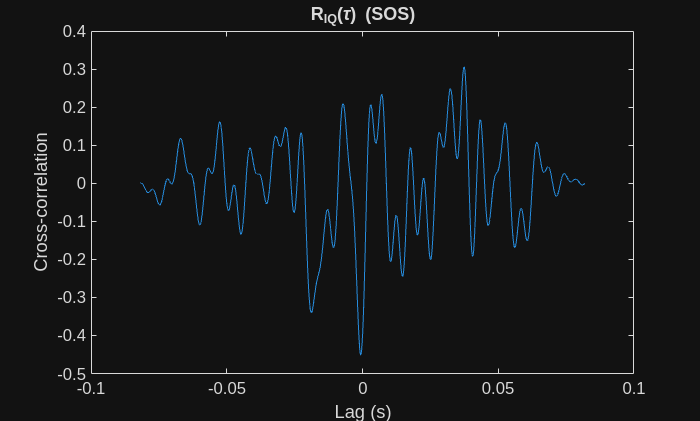


v = 30;    % 30m/s
fc = 2e9;  % 2GHz
B = 1e5;   % 100kHz
Ts = 1e-5; % 10microseconds
N = 8192;

p = 50;
C = 3e8;
fd = v*fc/C;

iter = 100;
Riq_avg = 0;
for i = 1:iter
    h = utils.SOS(fd, Ts, N0, N);
    
    hI = real(h);
    hQ = imag(h);
    % w = (randn(1, N) + 1j*randn(1, N))/sqrt(2); hI = real(w); hQ = imag(w);
    
    [Riq, lags] = xcorr(hI, hQ, 'biased');
    % compute Riq
    Riq_avg = Riq_avg + Riq;
end
Riq_avg = Riq_avg / iter;
% idx = abs(lags) < 50;
% plot(lags(idx)*Ts, Riq(idx));
figure;
plot(lags*Ts, Riq);
xlabel('Lag (s)');
ylabel('Cross-correlation');
title("R_{IQ}(\tau) (SOS)");

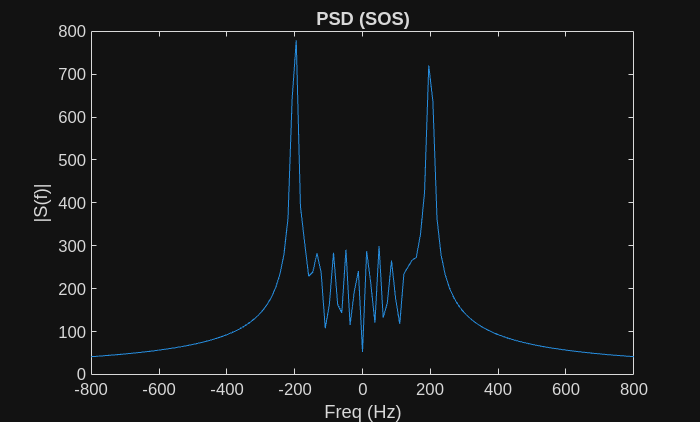

F = fft(Rh_avg);
Nfft = length(F);
f = (-Nfft/2: 1: Nfft/2-1)/(Nfft*Ts);
figure;
plot(f, abs(fftshift(F)))
xlim([-4*fd 4*fd])
xlabel('Freq (Hz)');
ylabel('|S(f)|');
title("PSD (SOS)");